close all 
clear all 

# Open Cleaned Data

load('Data2.mat','-mat','T_time');
load('Data2.mat','-mat','T');
load('Data2.mat','-mat','H');
t = T_time;



# Visualise Data

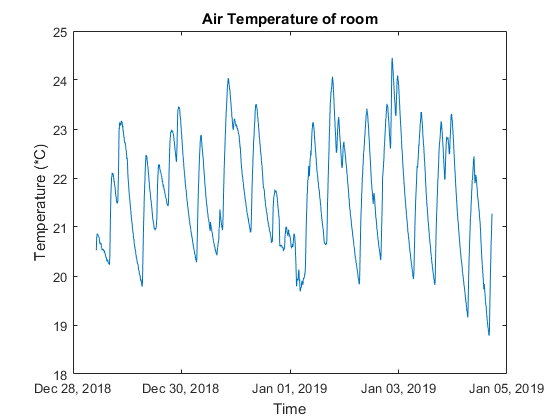

figure()
plot(t,T)
title('Air Temperature of room')
xlabel('Time')
ylabel('Temperature (*C)')
set(gcf,'color','w');

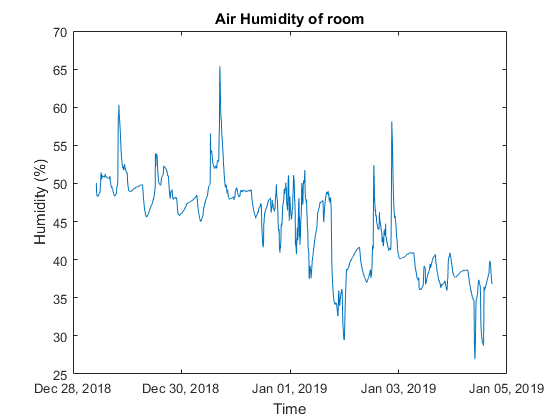

figure()
plot(t,H)
title('Air Humidity of room')
xlabel('Time')
ylabel('Humidity (%)')
set(gcf,'color','w');

# Normalise Data

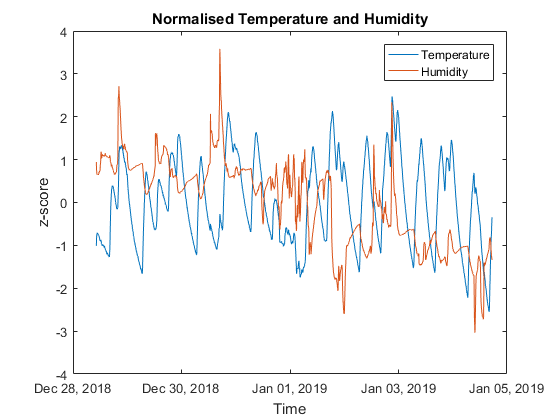

T_norm = zscore(T); 
H_norm = zscore(H); 

figure() 
plot(t, T_norm, t, H_norm)
title('Normalised Temperature and Humidity')
xlabel('Time')
ylabel('z-score')
legend('Temperature', 'Humidity') 
set(gcf,'color','w');

# Smooth Data

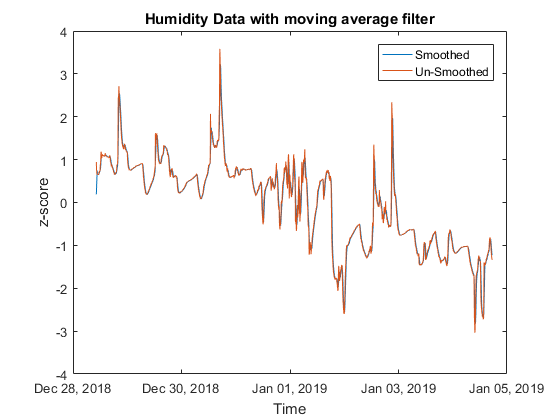

windowSize = 5;
b = (1/windowSize)*ones(1,windowSize);
a = 1;

y = filter(b,a,H_norm);
figure() 
plot(t, y, t, H_norm)

title('Humidity Data with moving average filter')
xlabel('Time')
ylabel('z-score')
legend('Smoothed', 'Un-Smoothed') 
set(gcf,'color','w');


H_norm = y;

# Seperate Data by Time Segements

Putting the data in a timetable makes it far easier to seperate out the data by time intervals. I've decided to seperate by day and plot seperately to get a better look at the data. The datasets do appear to be inversely related. 

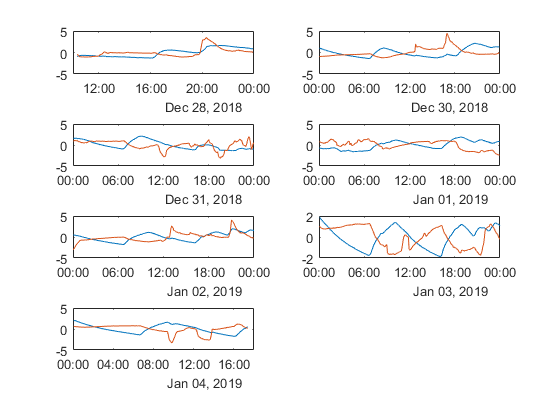

varNames = {'Temperature','Humidity'};

%Table = table(t,T,H,'VariableNames',varNames);
TT = timetable(t,T,H,'VariableNames',varNames);
TR = timerange('2018-12-28 00:00:00','2018-12-29 00:00:00');
Day1 = TT(TR,:);
TR = timerange('2018-12-30 00:00:00','2018-12-31 00:00:00');
Day2 = TT(TR,:);
TR = timerange('2018-12-31 00:00:00','2019-01-01 00:00:00');
Day3 = TT(TR,:);
TR = timerange('2019-01-01 00:00:00','2019-01-02 00:00:00');
Day4 = TT(TR,:);
TR = timerange('2019-01-02 00:00:00','2019-01-03 00:00:00');
Day5 = TT(TR,:);
TR = timerange('2019-01-03 00:00:00','2019-01-04 00:00:00');
Day6 = TT(TR,:);
TR = timerange('2019-01-04 00:00:00','2019-01-05 00:00:00');
Day7 = TT(TR,:);


figure()
subplot(4,2,1)
plot(Day1.Time, zscore(Day1.Temperature), Day1.Time, zscore(Day1.Humidity))
subplot(4,2,2)
plot(Day2.Time, zscore(Day2.Temperature), Day2.Time, zscore(Day2.Humidity))
subplot(4,2,3)
plot(Day3.Time, zscore(Day3.Temperature), Day3.Time, zscore(Day3.Humidity))
subplot(4,2,4)
plot(Day4.Time, zscore(Day4.Temperature), Day4.Time, zscore(Day4.Humidity))
subplot(4,2,5)
plot(Day5.Time, zscore(Day5.Temperature), Day5.Time, zscore(Day5.Humidity))
subplot(4,2,6)
plot(Day6.Time, zscore(Day6.Temperature), Day6.Time, zscore(Day6.Humidity))
subplot(4,2,7)
plot(Day7.Time, zscore(Day7.Temperature), Day7.Time, zscore(Day7.Humidity))
set(gcf,'color','w');

# Autocorrelation

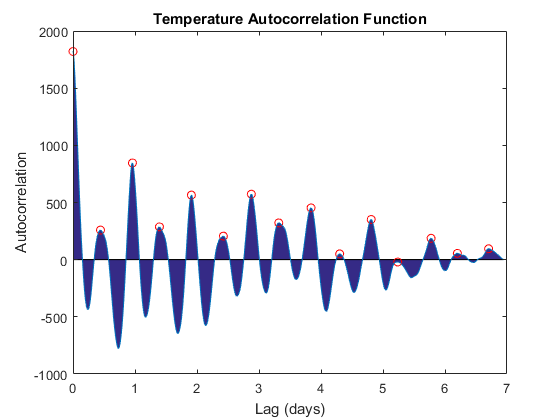

T_period = 261.8; %seconds per sample

[autocor,lags]= xcorr(T_norm,1821);
[pksh,lcsh] = findpeaks(autocor);
short = mean(diff(lcsh))/T_period;
%[pklg,lclg] = findpeaks(autocor, ...
%    'MinPeakDistance',ceil(short)*fs,'MinPeakheight',0.3);
%long = mean(diff(lclg))/fs

figure()
area(lags/T_period, autocor)
hold on
plot(lags(lcsh)/T_period,pksh,'or',lags/T_period,autocor)
xlabel('Lag (days)')
ylabel('Autocorrelation')
title('Temperature Autocorrelation Function')
axis([0 7 -1000 2000])
set(gcf,'color','w');


short

short = 0.4788

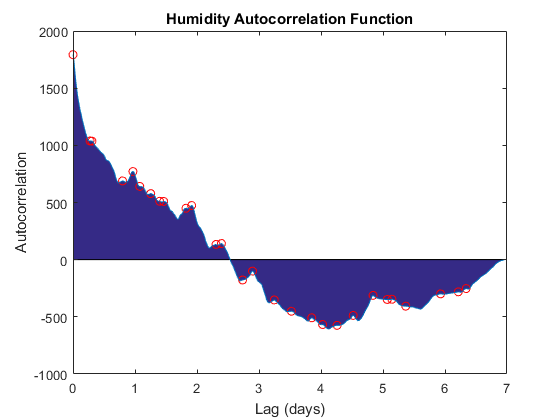


[autocor,lags]= xcorr(H_norm,1821);
[pksh,lcsh] = findpeaks(autocor);
short = mean(diff(lcsh))/T_period;
[pklg,lclg] = findpeaks(autocor, ...
    'MinPeakDistance',ceil(short)*T_period,'MinPeakheight',0.3);
long = mean(diff(lclg))/T_period;


figure()
area(lags/T_period, autocor)
hold on
plot(lags(lcsh)/T_period,pksh,'or',lags/T_period,autocor)
xlabel('Lag (days)')
ylabel('Autocorrelation')
title('Humidity Autocorrelation Function')
axis([0 7 -1000 2000])
set(gcf,'color','w');



short

short = 0.2348

long % days

long = 1.1975

The autocorrelation functions showed seasonality for both Temperature and Humidity time series data sets. 

## Temeperature: 0.5 days

## Humidity: 0.25 day and every 1.2 days 

# Cross Correlation

`xcorr(T,H)` returns the cross-correlation of the two discrete-time sequences. Cross-correlation measures the similarity between T  and shifted (lagged) copies of H as a function of the lag.

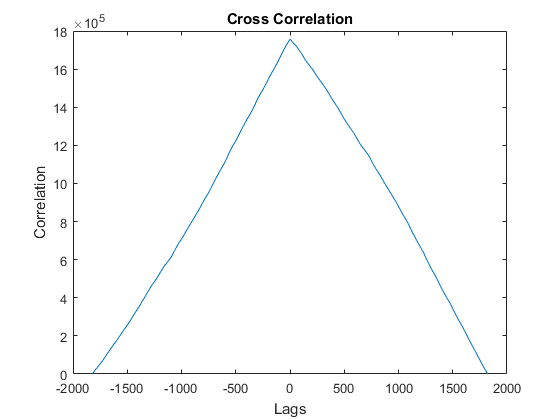

[r, lags] = xcorr(T,H);

figure()
plot(lags,r)
title('Cross Correlation')
xlabel('Lags')
ylabel('Correlation')
set(gcf,'color','w');


[~,I] = max(abs(r));
lagDiff = lags(I)

lagDiff = 0

timeDiff = lagDiff/T_period

timeDiff = 0

# Pearson Correlation

[rho, pval] = corr(T,H)

rho = -0.0666

pval = 0.0044

This p value shows a weak but statistically significant correlation? 

# Relationship between T and H

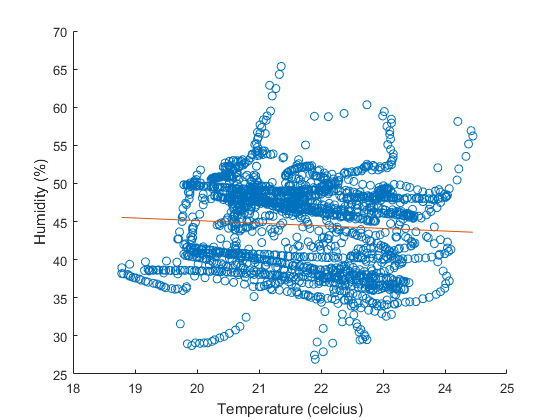

figure()
scatter(T,H)
hold on
fit = polyfit(T,H,1);
plot(T,polyval(fit,T));
xlabel('Temperature (celcius)') 
ylabel('Humidity (%)')
set(gcf,'color','w');


mdl = fitlm(T,H)

mdl = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      51.988     2.6118     19.905    6.3803e-80
    x1             -0.34305    0.12041    -2.8491     0.0044337


Number of observations: 1822, Error degrees of freedom: 1820
Root Mean Squared Error: 5.79
R-squared: 0.00444,  Adjusted R-Squared 0.00389
F-statistic vs. constant model: 8.12, p-value = 0.00443

mdl.Rsquared.Ordinary

ans = 0.0044

The coefficient of determination R squared value of 0.0044 is exceptionally low indicating that a linear approximation is not a good way of estimating the relationship between Temperature and Humidity.

# Relationship between T and H by Day

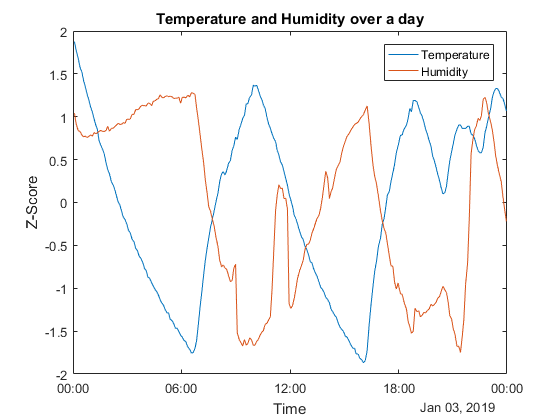

day = Day6;
dT = diff(day.Temperature); 
dH = diff(day.Humidity); 

windowSize = 10;
b = (1/windowSize)*ones(1,windowSize);
a = 1;

dH = filter(b,a,dH);


figure() 
plot(day.Time(1:length(day.Temperature)), zscore(day.Temperature))
hold on 
plot(day.Time(1:length(day.Humidity)), zscore(day.Humidity))
xlabel('Time')
ylabel('Z-Score')
legend('Temperature', 'Humidity')
title('Temperature and Humidity over a day')
set(gcf,'color','w');

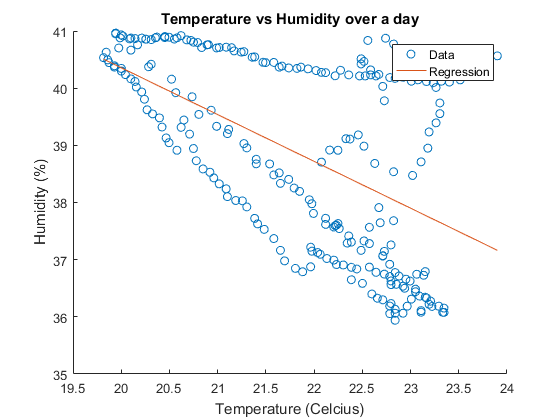


figure()

scatter(day.Temperature, day.Humidity)
hold on
fit = polyfit(day.Temperature,day.Humidity,1);
plot(day.Temperature,polyval(fit,day.Temperature));
xlabel('Temperature (Celcius)')
ylabel('Humidity (%)')
legend('Data', 'Regression')
title('Temperature vs Humidity over a day')
set(gcf,'color','w');

mdl = fitlm(day.Temperature,day.Humidity)

mdl = 
Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)      56.732     1.7959     31.591    3.4248e-88
    x1             -0.81877    0.08207    -9.9765    7.0225e-20


Number of observations: 246, Error degrees of freedom: 244
Root Mean Squared Error: 1.4
R-squared: 0.29,  Adjusted R-Squared 0.287
F-statistic vs. constant model: 99.5, p-value = 7.02e-20

rsquare = mdl.Rsquared.Ordinary

rsquare = 0.2897



%{
figure() 
plot(day.Time(1:length(dT)), dT)
hold on 
plot(day.Time(1:length(dH)), dH)


figure()
scatter(dT, dH)
xlabel('Δ Temperature (celcius)') 
ylabel('Δ Humidity (%)')
hold on 
fit = polyfit(dT,dH,1);
plot(dT,polyval(fit,dT));
mdl = fitlm(dT,dH)
rsquare = mdl.Rsquared.Ordinary
%}


# Predicting Humidity from Temperature

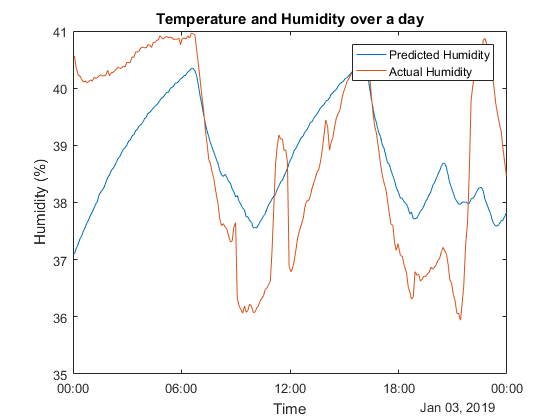

day = Day6;
Temp = day.Temperature; 
Humid_predict = -0.82*Temp + 56.7; 

figure()  
plot(day.Time(1:length(day.Humidity)), Humid_predict)
hold on 
plot(day.Time(1:length(day.Humidity)), day.Humidity)
xlabel('Time')
ylabel('Humidity (%)')
legend('Predicted Humidity','Actual Humidity')
title('Temperature and Humidity over a day')
set(gcf,'color','w');

# ARIMA - Temperature

% for temperature
% data from 4 days

TR = timerange('2019-01-02 00:00:00','2019-01-04 00:00:00');
past_data = TT(TR,:);
%past_data = Day6;
T_past = past_data.Temperature;
y = length(T_past);

%sys = armax(T_past,[11 50]);
Mdl = arima('Constant',0,'D',1,'Seasonality',250, 'SMALags',125);
EstMdl = estimate(Mdl,T_past);

 
    ARIMA(0,1,0) Model Seasonally Integrated with Seasonal MA(125):
    ---------------------------------------------------------------
    Conditional Probability Distribution: Gaussian

                                  Standard          t     
     Parameter       Value          Error       Statistic 
    -----------   -----------   ------------   -----------
     Constant              0         Fixed          Fixed
      SMA{125}      -0.245869     0.0451976       -5.43986
     Variance     0.00318172   8.13088e-05        39.1313


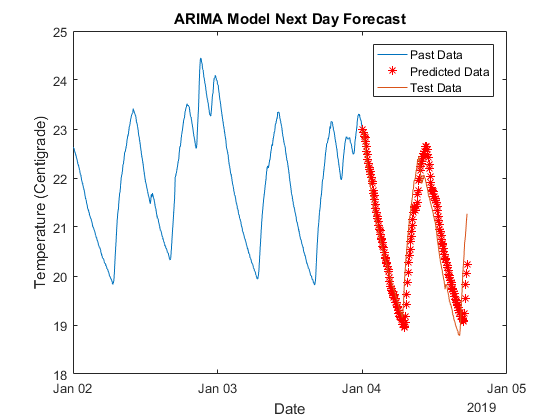


test_data = Day7;

steps = height(test_data);
yf = forecast(EstMdl,steps,'Y0',T_past);

figure()
plot(past_data.Time, past_data.Temperature , test_data.Time, yf, '*r',test_data.Time, test_data.Temperature);
legend('Past Data','Predicted Data', 'Test Data')
set(gcf,'color','w');
xlabel('Date')
ylabel('Temperature (Centigrade)')
title('ARIMA Model Next Day Forecast')

% for humidity
% data from 4 days

TR = timerange('2018-01-02 00:00:00','2019-01-04 00:00:00');
past_data = TT(TR,:);
%past_data = Day6;

windowSize = 30;
b = (1/windowSize)*ones(1,windowSize);
a = 1;


T_past = past_data.Humidity;
T_past = filter(b,a,T_past);
y = length(T_past);

%sys = armax(T_past,[11 50]);
Mdl = arima('Constant',0,'D',1,'Seasonality',230, 'SMALags',230);
EstMdl = estimate(Mdl,T_past);

 
    ARIMA(0,1,0) Model Seasonally Integrated with Seasonal MA(230):
    ---------------------------------------------------------------
    Conditional Probability Distribution: Gaussian

                                  Standard          t     
     Parameter       Value          Error       Statistic 
    -----------   -----------   ------------   -----------
     Constant              0         Fixed          Fixed
      SMA{230}       -0.23531       0.02128       -11.0578
     Variance      0.0867683   0.000956907        90.6757


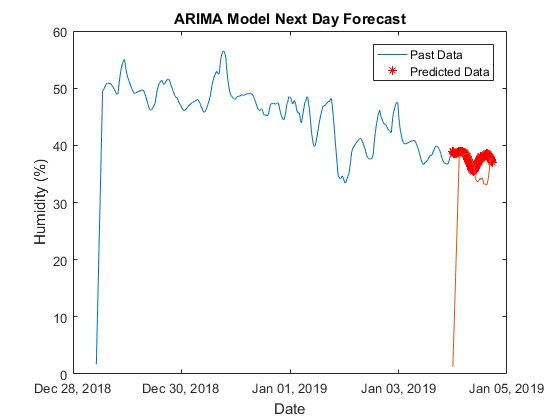


test_data = Day7;

steps = height(test_data);
yf = forecast(EstMdl,steps,'Y0',T_past);

figure()
plot(past_data.Time, T_past , test_data.Time, yf, '*r',test_data.Time, filter(b,a,test_data.Humidity));
legend('Past Data','Predicted Data')
set(gcf,'color','w');
xlabel('Date')
ylabel('Humidity (%)')
title('ARIMA Model Next Day Forecast')